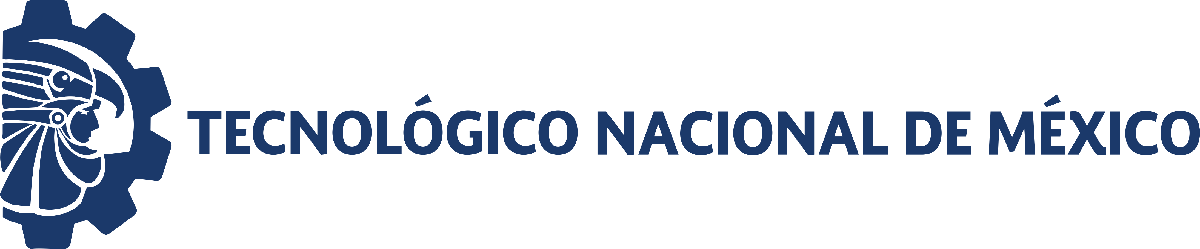                                 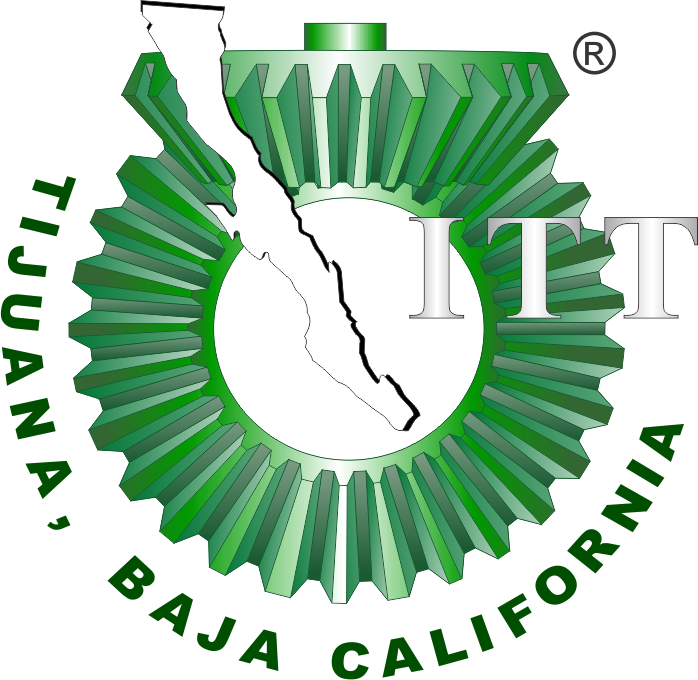

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

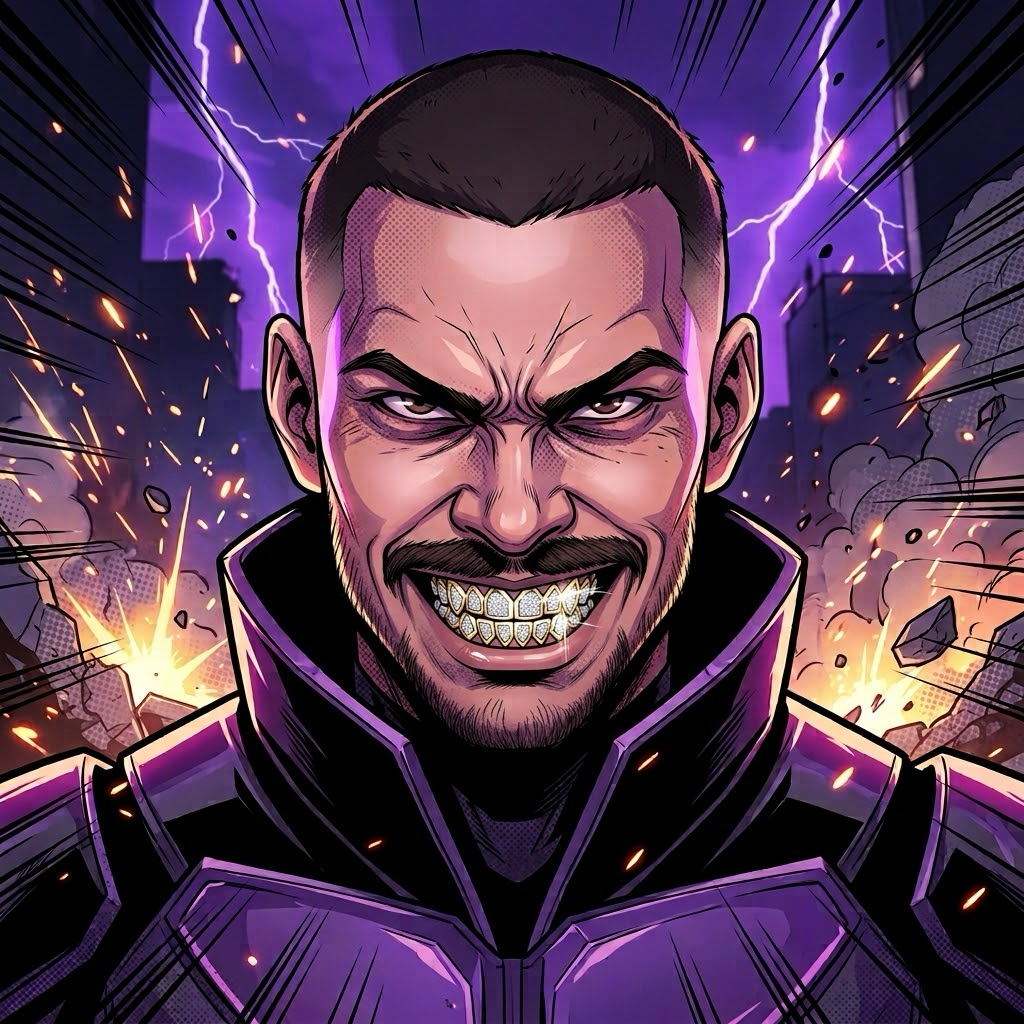

Nombre del alumno: Emilisno Villalobos García

Número de control: 23212243

Correo institucional: l23212243**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema1')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al escalón

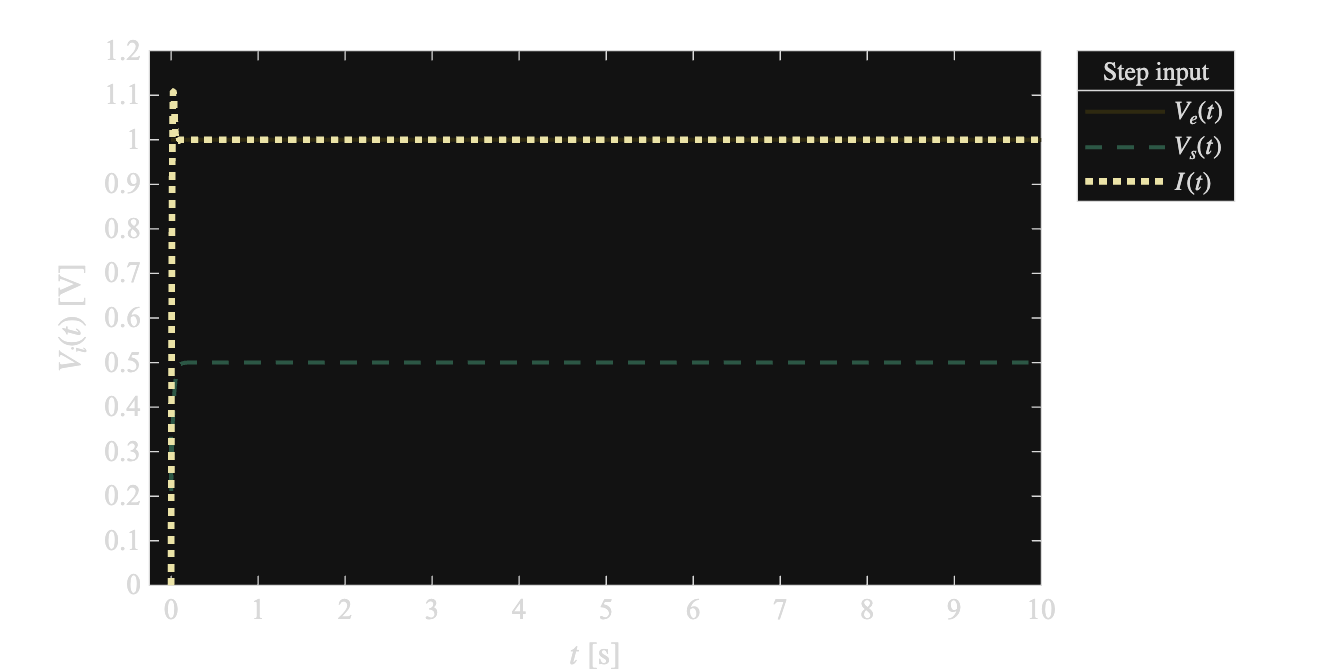

set_param('Sistema1/S1','sw','1')
set_param('Sistema1/Ve(t)','sw','1')
x1 = sim('Sistema1', parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.PID,'Step')

## Respuesta al impulso

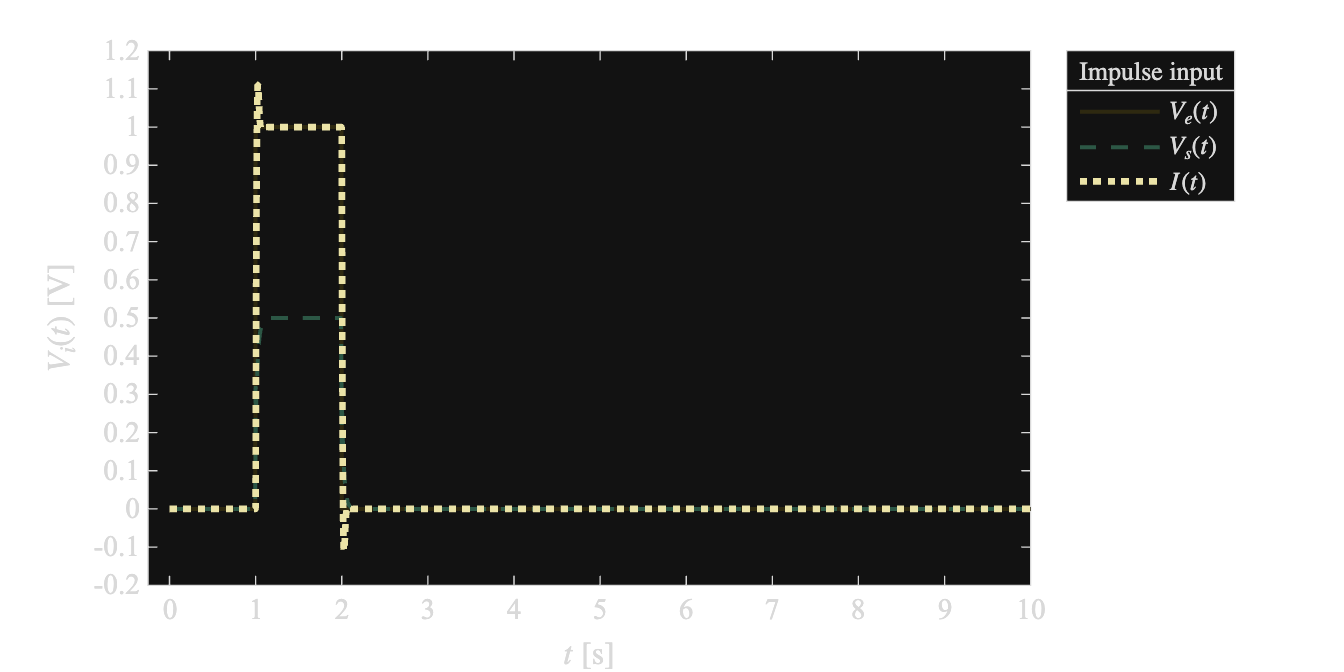

set_param('Sistema1/S1','sw','0')
set_param('Sistema1/Ve(t)','sw','1')
x2 = sim('Sistema1', parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.PID,'Impulse')

## Respuesta a la rampa

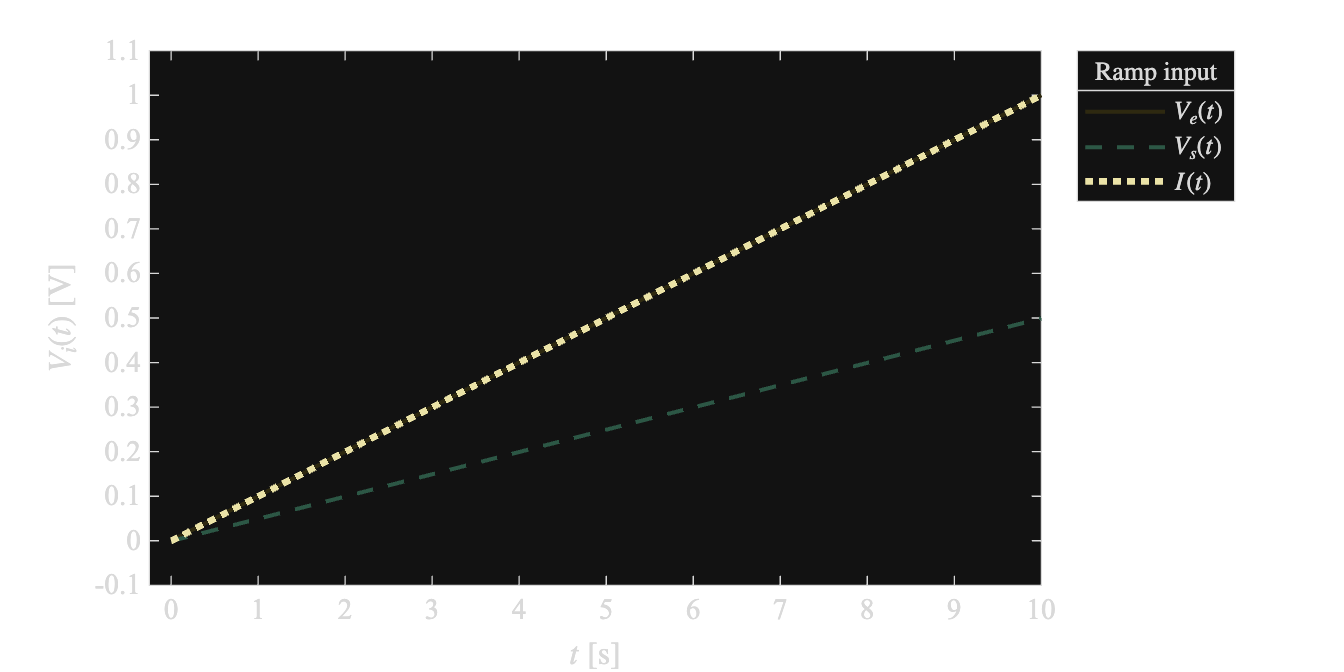

set_param('Sistema1/S2','sw','1')
set_param('Sistema1/Ve(t)','sw','0')
x3 = sim('Sistema1', parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

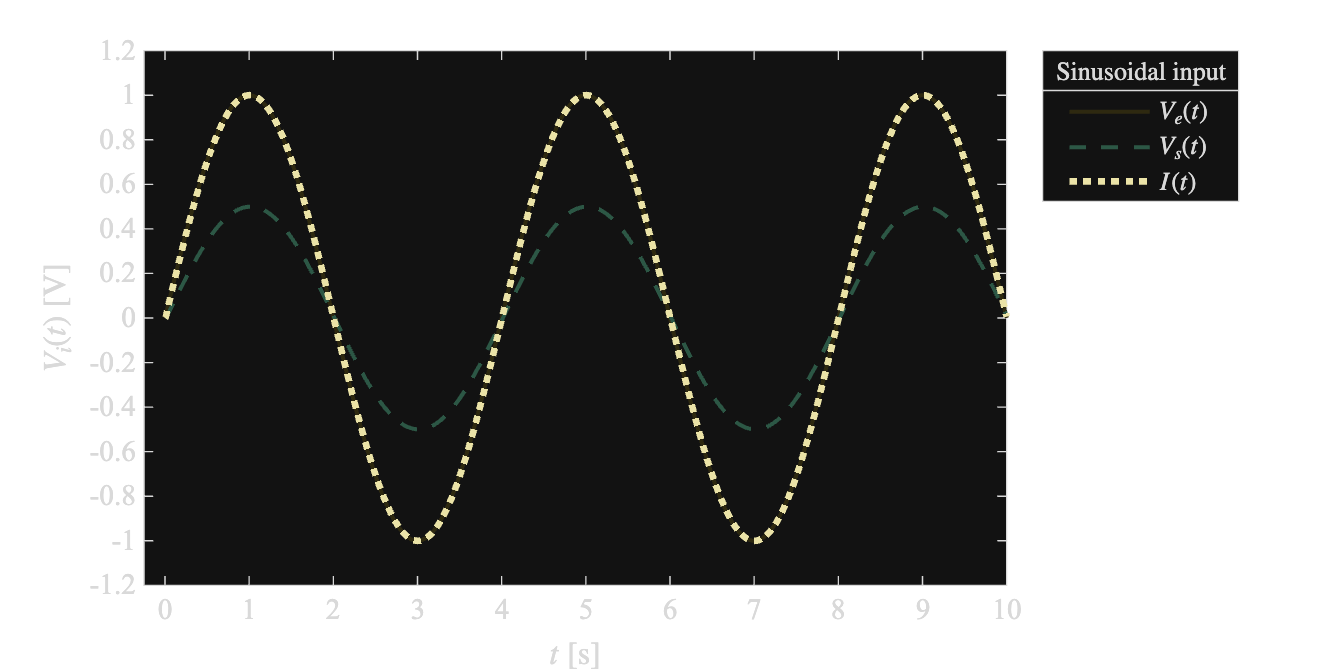

set_param('Sistema1/S2','sw','0')
set_param('Sistema1/Ve(t)','sw','0')
x4 = sim('Sistema1', parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.PID,'Sinusoidal')

## Función: Respuesta de la simulación

function plotsignals(t,Ve,Vs,PID,signal)
    set (figure(), 'color', 'w')
    set (gcf, 'units', 'inches', 'position',[1,1,7,3.5])
    set (gca, 'fontname', 'times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [46, 41, 16]/255;
    clr2 = [44, 87, 69]/255;
    clr3 = [235, 227, 167]/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot (t,Ve,'-','Linewidth',1.5,'Color',clr1)
    plot (t,Vs,'--','LineWidth',1.5,'Color',clr2)
    plot (t,PID,':','LineWidth',2.5,'Color',clr3)
    L = legend('$V_e(t)$','$V_s(t)$','$I(t)$');
    set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
        
    title(L,[signal,' input'])
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)

        if signal == "Step"
            ylim([0 1.2]); yticks(0:0.1:1.2)
        elseif signal == "Impulse"
            ylim([-0.2 1.2]); yticks (-0.2:0.1:1.2)
        elseif signal == "Ramp"
            ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
        elseif signal == "Sinusoidal"
            ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
        end

        exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end